Importing the Data

data = readtable("weather-energy-data-update.csv")

data = 26328×18 table
        Datetime         kWh     hour    day_of_month    day_of_week    month    is_weekend    pressure_at_sea    precip_dur_past10min    wind_dir    wind_speed    temp_dew    pressure    visib_mean_last10min    temp_dry    humidity    cloud_cover    visibility
    ________________    _____    ____    ____________    ___________    _____    __________    _______________    ____________________    ________    __________    ________    ________    <


t = table2array(data(:,1));
consume = table2array(data(:,2));

Configuration of Load l(t) and Time t  before entry into model

load_t = [];
hour = 1;
T = 24;
hours = [];

% Configuration of Time Data

for i = 1:24
    hours = [hours; i];
end

start_date = t(1);
start_date.Format = 'dd-MMM-yyyy';
end_date = t(length(t));
end_date.Format = 'dd-MMM-yyyy';
time = start_date:caldays(1):end_date;

% Configuration of Consumption Data

for i = 1:(length(consume)/24)
    load_t = [load_t consume(hour:T)];
    hour = hour + 24;
    T = T + 24;
end

load_t = load_t'; % Transposing l(t) with dimension 1097 days x 24 hours

We have conusmption data of 1097 days. Let's visualize Load l(t) versus time t for first 10 days

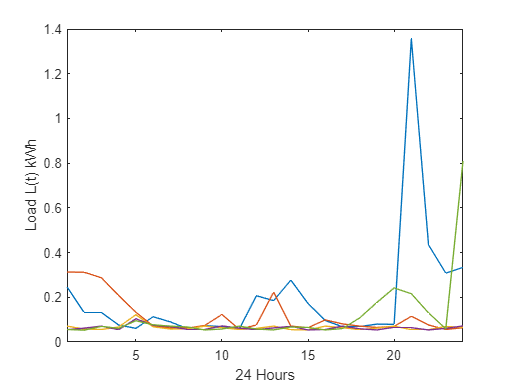

plot(hours, load_t(1:5,:))
xlabel("24 Hours")
ylabel("Load L(t) kWh")
xlim([1 24])

Computing the average load per hour for 1097 days

l_bar = [];

for i = 1:24
    l = 0;
    for d = 1:length(load_t)
        l = l + load_t(d,i);
    end
    l_bar = [l_bar (l/length(load_t))];
end

l_bar = l_bar';

e_t = load_t;

for i = 1:24
    e_t(:,i) = e_t(:,i) - l_bar(i);
end

% Define the percentage of data to use for training
train_percent = 0.8;

% Use cvpartition to split the data into training and test sets
cv = cvpartition(size(e_t, 1), 'HoldOut', 1 - train_percent);
train_data = e_t(cv.training, :);
test_data = e_t(cv.test, :);

bank = []


bank =

     []




for i = 1:24

    % Fit an ARIMA model to the training data
    Mdl = arima('D', 1, 'Seasonality', 24, 'MALags', 24, 'SMALags', 24, 'SARLags', 24, 'Constant', 1);
    fit = estimate(Mdl, train_data(:,i));

    % Generate forecasts for the test set
    num_periods = size(test_data, 1);
    forecast_data = forecast(fit, num_periods, 'Y0', train_data(:,i));

    bank = [bank forecast_data]

end

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0              Inf             0
    SAR{24}     -0.84299      0.013765          -61.242             0
    MA{24}       0.60285         54550       1.1051e-05       0.99999
    SMA{24}      0.60285         54550       1.1051e-05       0.99999
    Variance     0.26516      0.014966           17.718    3.0357e-70



bank =    -0.3616
    0.0891
    0.9847
    1.1350
    1.4841
    1.6522
    2.1991
    2.5039
    2.7655
    3.2406


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0              Inf             0
    SAR{24}     -0.81995      0.010969          -74.752             0
    MA{24}         0.655         97675       6.7059e-06       0.99999
    SMA{24}        0.655         97675       6.7059e-06       0.99999
    Variance     0.21447      0.012691           16.899    4.5706e-64



bank =    -0.3616    0.1734
    0.0891    0.5588
    0.9847    0.9935
    1.1350    1.3249
    1.4841    1.8323
    1.6522    2.5633
    2.1991    2.4171
    2.5039    2.7777
    2.7655    3.1466
    3.2406    3.4997


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0              Inf             0
    SAR{24}     -0.78209      0.012135          -64.452             0
    MA{24}       0.71792         29858       2.4045e-05       0.99998
    SMA{24}      0.71792         29858       2.4045e-05       0.99998
    Variance     0.16206      0.011368           14.256    4.1124e-46



bank =    -0.3616    0.1734   -0.5989
    0.0891    0.5588   -0.1682
    0.9847    0.9935    0.9899
    1.1350    1.3249    0.4281
    1.4841    1.8323    0.8035
    1.6522    2.5633    1.2324
    2.1991    2.4171    1.5086
    2.5039    2.7777    1.8397
    2.7655    3.1466    2.1524
    3.2406    3.4997    2.4974


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0            Inf               0
    SAR{24}     -0.77785       0.01162        -66.943               0
    MA{24}       0.72617      0.014095         51.519               0
    SMA{24}      0.72617      0.014095         51.519               0
    Variance     0.15477      0.010429         14.841      8.0101e-50



bank =    -0.3616    0.1734   -0.5989    0.2578
    0.0891    0.5588   -0.1682    0.6549
    0.9847    0.9935    0.9899    1.0076
    1.1350    1.3249    0.4281    1.3513
    1.4841    1.8323    0.8035    1.6886
    1.6522    2.5633    1.2324    2.7762
    2.1991    2.4171    1.5086    2.3859
    2.5039    2.7777    1.8397    2.6986
    2.7655    3.1466    2.1524    2.9439
    3.2406    3.4997    2.4974    3.3273


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0              Inf             0
    SAR{24}     -0.75333      0.010008          -75.271             0
    MA{24}       0.75987         16224       4.6835e-05       0.99996
    SMA{24}      0.75987         16224       4.6835e-05       0.99996
    Variance     0.13312      0.012009           11.085    1.4766e-28



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013
    0.0891    0.5588   -0.1682    0.6549    0.6175
    0.9847    0.9935    0.9899    1.0076    0.9848
    1.1350    1.3249    0.4281    1.3513    1.2856
    1.4841    1.8323    0.8035    1.6886    1.5576
    1.6522    2.5633    1.2324    2.7762    1.8546
    2.1991    2.4171    1.5086    2.3859    2.2879
    2.5039    2.7777    1.8397    2.6986    2.5729
    2.7655    3.1466    2.1524    2.9439    2.8950
    3.2406    3.4997    2.4974    3.3273    3.1451


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1              0             Inf             0
    SAR{24}     -0.73221      0.0082846         -88.383             0
    MA{24}       0.79865          98956      8.0708e-06       0.99999
    SMA{24}      0.79865          98956      8.0707e-06       0.99999
    Variance     0.11801       0.012818          9.2068    3.3611e-20



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528
    3.2406    3.4997    2.4974    3.3273    3.1451    3.0301


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          1              0             Inf             0
    SAR{24}     -0.7274      0.0079122         -91.933             0
    MA{24}      0.80944           8584      9.4296e-05       0.99992
    SMA{24}     0.80944         8584.1      9.4296e-05       0.99992
    Variance    0.11658       0.011238          10.374    3.2594e-25



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528    2.6124
    3.2406    3.4997    2.4974    3.3273    3.1451    3.0301    3.0899


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1              0           Inf               0
    SAR{24}     -0.72867      0.0078241       -93.132               0
    MA{24}       0.81077        0.01412        57.419               0
    SMA{24}      0.81077        0.01412        57.419               0
    Variance     0.11883      0.0099725        11.915      9.8408e-33



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.4350
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528    2.6124    2.5378
    3.2406    3.4997    2.4974    3.3273    3.1451    3.0301    3.0899    3.1003


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1              0             Inf             0
    SAR{24}     -0.72903      0.0077735         -93.783             0
    MA{24}       0.80974          12046      6.7218e-05       0.99995
    SMA{24}      0.80974          12046      6.7218e-05       0.99995
    Variance     0.11779       0.010459          11.262    2.0172e-29



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.4350    2.4931
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528    2.6124    2.5378    2.7623
    3.2406    3.4997    2.4974    3.3273    3.1451    3.0301    3.0899    3.1003    4.2998


 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1              0             Inf             0
    SAR{24}     -0.78562       0.015266         -51.464             0
    MA{24}       0.70952     2.5118e+05      2.8248e-06             1
    SMA{24}      0.70952     2.5118e+05      2.8248e-06             1
    Variance     0.18298       0.011989          15.262    1.3649e-52



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865    3.4463
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.4350    2.4931    2.4020
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528    2.6124    2.5378    2.7623    2.9028
    3.2406    3.4997    2.4974    3.3273    3.1451    3.0301    3.0899    3.1003    

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.84207       0.02354        -35.771      3.0892e-280
    MA{24}        0.6488       0.27036         2.3998         0.016406
    SMA{24}       0.5744       0.28949         1.9842         0.047236
    Variance     0.27803      0.014713         18.897       1.2068e-79



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865    3.4463    2.2425
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.4350    2.4931    2.4020    2.8051
    2.7655    3.1466    2.1524    2.9439    2.8950    2.8528    2.6124    2.5378    2.7623    2.9028    3

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0              Inf              0
    SAR{24}     -0.88153      0.024244          -36.361    1.7539e-289
    MA{24}        0.5684         10607       5.3585e-05        0.99996
    SMA{24}       0.5684         10607       5.3585e-05        0.99996
    Variance     0.34812      0.017525           19.864     8.3883e-88



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865    3.4463    2.2425    2.4786
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.4350    2.4931    2.4020    2.8051    3.0681
    2.7655    3.1466    2

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0            Inf               0
    SAR{24}     -0.85104      0.021799         -39.04               0
    MA{24}       0.73567      0.055329         13.296      2.4332e-40
    SMA{24}       0.3428       0.06921          4.953      7.3078e-07
    Variance     0.39755      0.019996         19.881      5.9161e-88



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389    2.0412
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865    3.4463    2.2425    2.4786    2.4859
    2.5039    2.7777    1.8397    2.6986    2.5729    2.5200    2.4678    2.

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.85858      0.024177        -35.513      3.1451e-276
    MA{24}       0.40794      0.074151         5.5016       3.7645e-08
    SMA{24}      0.72233      0.064225         11.247       2.3983e-29
    Variance      0.3762      0.018742         20.072       1.2948e-89



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389    2.0412    2.0621
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3865    3.4463    2.2425    2.4786    2.4859    2.6679
    2.

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          1             0            Inf               0
    SAR{24}     -0.8804      0.022726        -38.739               0
    MA{24}       0.6801      0.087213         7.7982      6.2821e-15
    SMA{24}     0.43265       0.10044         4.3074      1.6518e-05
    Variance    0.38758      0.018657         20.775      7.3402e-96



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389    2.0412    2.0621    2.1395
    2.1991    2.4171    1.5086    2.3859    2.2879    2.3329    2.2910    2.1618    2.3

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0            Inf               0
    SAR{24}     -0.86366      0.022526         -38.34      1.334e-321
    MA{24}       0.69877      0.079681         8.7696       1.793e-18
    SMA{24}      0.43613      0.093019         4.6887      2.7501e-06
    Variance     0.36609      0.018497         19.792      3.4875e-87



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634    1.7851
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389    2.0412    2.0621    2.1395    2.0154
    2.1991    2.4171    1.5

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant          1             0            Inf               0
    SAR{24}     -0.8607      0.021936        -39.237               0
    MA{24}      0.61266       0.27188         2.2534        0.024233
    SMA{24}     0.53254       0.28584         1.8631        0.062453
    Variance    0.33315      0.016734         19.909      3.4186e-88



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634    1.7851    1.8592
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.9819    1.8685    2.0201    2.0389    2.0412    2.06

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0              Inf              0
    SAR{24}     -0.84951       0.02186          -38.862              0
    MA{24}       0.57199         15230       3.7558e-05        0.99997
    SMA{24}      0.57199         15230       3.7558e-05        0.99997
    Variance     0.32276      0.015103           21.371    2.4651e-101



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634    1.7851    1.8592    1.9780
    1.6522    2.5633    1.2324    2.7762    1.8546    1.9034    2.0036    1.8191    1.98

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0              Inf             0
    SAR{24}     -0.87631      0.020078          -43.646             0
    MA{24}       0.57233         50392       1.1358e-05       0.99999
    SMA{24}      0.57233         50392       1.1358e-05       0.99999
    Variance     0.32544      0.016607           19.597    1.6398e-85



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634    1.7851    1.8592    1.9780    1.4862
    1.6522    2.5633    1.2324    2.77

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.86039       0.02309        -37.262      6.7661e-304
    MA{24}       0.36506      0.099301         3.6763       0.00023667
    SMA{24}      0.65726      0.089007         7.3844       1.5312e-13
    Variance     0.47895       0.02312         20.716        2.494e-95



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449    0.4225
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590    0.6309
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165    1.4986
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427    1.2176
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.8634    1.7851    1.8592    1.9780    1.486

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.88022      0.020678        -42.568                0
    MA{24}       0.79115       0.03934         20.111       5.9284e-90
    SMA{24}      0.14453      0.047725         3.0283        0.0024596
    Variance     0.64465      0.028016          23.01      3.7315e-117



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449    0.4225    1.3490
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590    0.6309    2.8229
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165    1.4986    1.9971
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427    1.2176    2.5426
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.5379    1.5908    1.5936    1.8209    1.863

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.87023      0.018985        -45.838                0
    MA{24}       0.87882      0.023127         37.999      5.9133e-316
    SMA{24}     0.024529      0.043591        0.56271          0.57363
    Variance     0.75842       0.03537         21.443      5.3505e-102



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449    0.4225    1.3490   -0.2196
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590    0.6309    2.8229    0.9081
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165    1.4986    1.9971    0.7201
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427    1.2176    2.5426    1.2153
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.6755    1.5545    1.3881    1.3516    1.537

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant           1             0            Inf                0
    SAR{24}     -0.87207      0.024719         -35.28      1.2009e-272
    MA{24}       0.22208      0.050801         4.3716       1.2333e-05
    SMA{24}      0.78693      0.040281         19.536       5.4394e-85
    Variance     0.51758      0.023954         21.607      1.5367e-103



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449    0.4225    1.3490   -0.2196    0.5731
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590    0.6309    2.8229    0.9081    0.9382
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165    1.4986    1.9971    0.7201    1.4802
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427    1.2176    2.5426    1.2153    1.7466
    1.4841    1.8323    0.8035    1.6886    1.5576    1.5658    1.675

 
    ARIMA(0,1,24) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           1             0            Inf               0
    SAR{24}     -0.83235      0.019539        -42.599               0
    MA{24}       0.44145       0.15338         2.8782       0.0039994
    SMA{24}      0.62147       0.13988         4.4427      8.8827e-06
    Variance     0.40414      0.019399         20.833      2.1637e-96



bank =    -0.3616    0.1734   -0.5989    0.2578    0.3013    0.3765    0.4226    0.3586    0.4515    0.0847    0.5234    0.2177    0.2502    0.3987    0.2041   -0.0286    0.2402    0.5712    0.5449    0.4225    1.3490   -0.2196    0.5731    0.6130
    0.0891    0.5588   -0.1682    0.6549    0.6175    0.5947    0.7225    0.6396    0.9777    0.3513    0.3481    1.6435    0.4915    1.3931    0.6508    1.1115    1.1081    1.1345    0.4590    0.6309    2.8229    0.9081    0.9382    0.9209
    0.9847    0.9935    0.9899    1.0076    0.9848    0.9952    0.9415    0.9708    1.1829    0.1897    1.2032    0.7384    0.6876    0.8475    0.7890    0.6846    0.8885    0.9662    0.7165    1.4986    1.9971    0.7201    1.4802    1.7385
    1.1350    1.3249    0.4281    1.3513    1.2856    1.2763    1.2212    1.1999    1.2685    0.9582    1.3484    2.4577    1.5252    1.5637    1.5311    2.0430    1.7020    1.4685    0.8427    1.2176    2.5426    1.2153    1.7466    1.7373
    1.4841    1.8323    0.803

Adding back to the equation to find and calculate the forecasted l(t)

load_forecast = bank;

for i = 1:24
    load_forecast(:,i) = load_forecast(:,i) + l_bar(i);
end

Visualize the 24-hour forecasted consumption compared with actual data

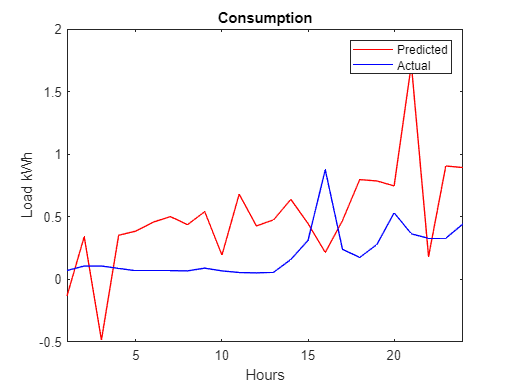

plot(hours, load_forecast(1,:), 'r', hours, load_t(879,:), 'b')
legend("Predicted", "Actual")
title("Consumption")
ylabel("Load kWh")
xlabel("Hours")
xlim([1 24])

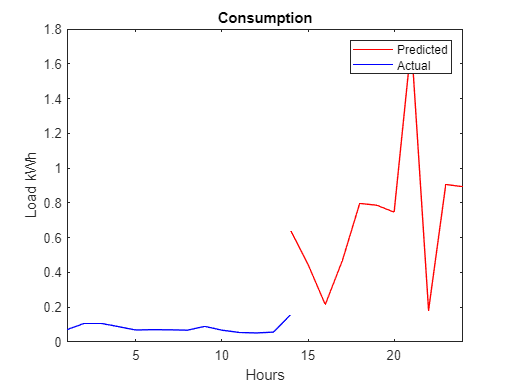


plot(14:24, load_forecast(1,14:24), 'r', 1:14, load_t(879,1:14), 'b')
legend("Predicted", "Actual")
title("Consumption")
ylabel("Load kWh")
xlabel("Hours")
xlim([1 24])

Configuration of output data format compatible for export

load_forecast = reshape(load_forecast', [],1);
time_forecast = t(((size(train_data,1)*24)+1):end);

load_measured = load_t(1:size(train_data,1),:);
load_measured = reshape(load_measured', [],1);
time_measured = t(1:(size(train_data,1)*24));

Exporting the Forecast onto Server in the format .xlsx

xlswrite('TimeSeriesForecasting.xlsx', {'Time','Measured Consumption','Future Time','Predicted Consumption'}, 'Sheet1','A1')
xlswrite('TimeSeriesForecasting.xlsx', cellstr(time_measured), 'Sheet1','A2');
xlswrite('TimeSeriesForecasting.xlsx', load_measured, 'Sheet1','B2');
xlswrite('TimeSeriesForecasting.xlsx', cellstr(time_forecast), 'Sheet1','C2');
xlswrite('TimeSeriesForecasting.xlsx', load_forecast, 'Sheet1','D2');